# Optimización lineal con restricciones utilizando el método Simplex en MATLAB

**Profesor:** PhD. Marlon E. Moscoso Martínez

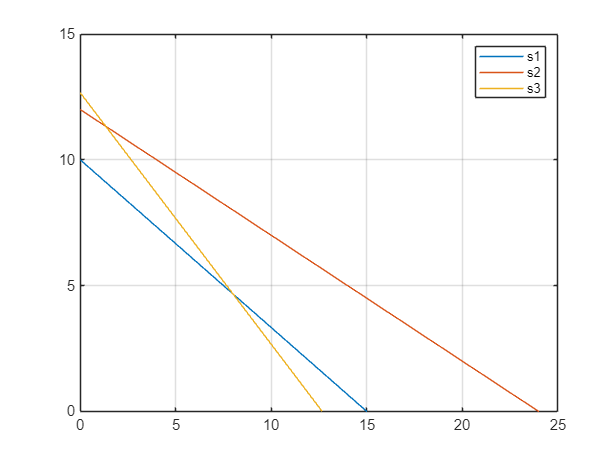

clear all; close all; clc

% Región factible:
x1 = linspace(0, 100, 1000);

x2 = -2/3*x1 + 10;
plot(x1, x2)
hold on
x2 = -1/2*x1 + 12;
plot(x1, x2)
x2 = -x1 + 38/3; % Es 100
plot(x1, x2)
legend('s1', 's2', 's3')
ylim([0 15])
xlim([0 25])
grid on



% Limpieza de la consola, variables y figuras
clc; clear; close all; format rational;

%% Paso 1: Definir los datos del problema

% Coeficientes de la función objetivo
C = [-8000, -6000];  % Minimizar Z = 10p1 + 15p2 (original minimización: se niega)

% Restricciones (coeficientes de las variables p1 y p2)
A = [2, 3; 3, 1];  % Restricciones: 2p1 + p2 >= 100, 3p1 + 6p2 >= 250 (se niega el signo, variables de exceso positivas)
b = [30; 38];  % Recursos disponibles

% Añadir variables de holgura
A = [A eye(2)];  % Añadir variables de holgura (dos restricciones)
C = [C, 0, 0];  % Extender la función objetivo con ceros para las variables de holgura

%% Paso 2: Configurar la tabla inicial de Simplex

% Número de restricciones y variables
m = size(A, 1);  % Número de restricciones
n = size(A, 2);  % Número de variables (incluyendo las de holgura)

% Crear la tabla Simplex inicial
tableau = [A b; C 0];  % Tabla Simplex con las restricciones y la función objetivo

% Mostrar la tabla inicial
disp('Tabla Simplex inicial:');

Tabla Simplex inicial:


disp(tableau);

       2              3              1              0             30       
       3              1              0              1             38       
   -8000          -6000              0              0              0       




%% Paso 3: Descomposición en soluciones básicas y no básicas

% Soluciones básicas: Las variables de holgura s1 y s2 están en la base inicialmente
% Las variables de decisión x1 y x2 no están en la base (variables no básicas)
basic_vars = [3, 4];  % Variables básicas (s1 y s2)
non_basic_vars = [1, 2];  % Variables no básicas (x1 y x2)

% Mostrar las variables básicas y no básicas
disp('Variables básicas (inicialmente):');

Variables básicas (inicialmente):


disp(basic_vars);

       3              4       



disp('Variables no básicas (inicialmente):');

Variables no básicas (inicialmente):


disp(non_basic_vars);

       1              2       




%% Paso 4: Realización del método Simplex - Pivoteo

iter = 0;  % Contador de iteraciones

while any(tableau(end, 1:end-1) < 0)  % Mientras haya coeficientes negativos en la fila de costos (función objetivo)
    iter = iter + 1;
    fprintf('\nIteración %d:\n', iter);
    
    % 1. Identificar la columna pivote (la más negativa en la fila de costos)
    [~, pivot_col] = min(tableau(end, 1:end-1));
    fprintf('Columna pivote: %d\n', pivot_col);
    
    % 2. Identificar la fila pivote (razones mínimas)
    ratios = tableau(1:end-1, end) ./ tableau(1:end-1, pivot_col);
    ratios(ratios <= 0) = inf;  % Ignorar razones no positivas
    [~, pivot_row] = min(ratios);
    fprintf('Fila pivote: %d\n', pivot_row);
    
    % 3. Realizar el pivoteo
    pivot_element = tableau(pivot_row, pivot_col);
    tableau(pivot_row, :) = tableau(pivot_row, :) / pivot_element;
    for i = 1:size(tableau, 1)
        if i ~= pivot_row
            tableau(i, :) = tableau(i, :) - tableau(i, pivot_col) * tableau(pivot_row, :);
        end
    end
    
    % Actualización de las variables básicas
    basic_vars(pivot_row) = pivot_col;
    
    % Mostrar la tabla después del pivoteo
    disp('Tabla Simplex después del pivoteo:');
    disp(tableau);
end


Iteración 1:


Columna pivote: 1


Fila pivote: 2


Tabla Simplex después del pivoteo:


       0              7/3            1             -2/3           14/3     
       1              1/3            0              1/3           38/3     
       0         -10000/3            0           8000/3       304000/3     




Iteración 2:


Columna pivote: 2


Fila pivote: 1


Tabla Simplex después del pivoteo:


       0              1              3/7           -2/7            2       
       1              0             -1/7            3/7           12       
       0              0          10000/7        12000/7       108000       




%% Paso 5: Extracción de la solución óptima

% Identificar las variables básicas en la solución final
x = zeros(n-1, 1);  % Inicializar el vector de soluciones
for j = 1:n-1  % Recorrer cada columna de la tabla original (sin contar b)
    col = tableau(1:end-1, j);
    if sum(col == 1) == 1 && sum(col == 0) == m-1  % Verificar si es columna de la identidad
        row = find(col == 1);  % Encontrar en qué fila está el 1
        x(j) = tableau(row, end);  % Asignar el valor de b correspondiente
    end
end

% Mostrar los resultados
fprintf('Valores óptimos de las variables de decisión:\n');

Valores óptimos de las variables de decisión:


disp(x(1:2));  % Mostrar los valores de las variables originales (x1 y x2)

      12       
       2       



fprintf('Valor óptimo de la función objetivo: %.2f\n', tableau(end, end));

Valor óptimo de la función objetivo: 108000.00
